#### General parameters 

These are the same 'options' used for the filtering and segmentation

opts.orig_file_dir = "../physionet.org/textdata/";
opts.abp_ann_dir = '../physionet.org/abp_ann/';
opts.segmented_file_dir = "../physionet.org/segmented_data/";
opts.clear_segmented_dir = false; %delete all existing files in segmented file directory
opts.segmented_abp_dir = "../physionet.org/segmented_abp_beats/";

opts.first_record_process = 180;
opts.last_record_process = 185; %use -1 to process all

opts.apply_filter = false;
opts.samp_freq = 125;
opts.filter.type = 'low';
opts.filter.cutoff = 15; %vector if bandpass
opts.filter.order = 3;

opts.apply_hampel_abp = false;
opts.apply_hampel_ppg = true;

opts.flats.derivative_thresh = 1e-3;
opts.flats.window = 300;
opts.flats.window_thresh = 0.5;
opts.min_region_length = opts.samp_freq*60;

opts.num_periods_per_segment = 20;

#### Systolic Peaks, Diastolic Peaks and Waveform Feet

See M. Elgendi "On the Analysis of Fingertip Photoplethysmogram Signals" p. 6

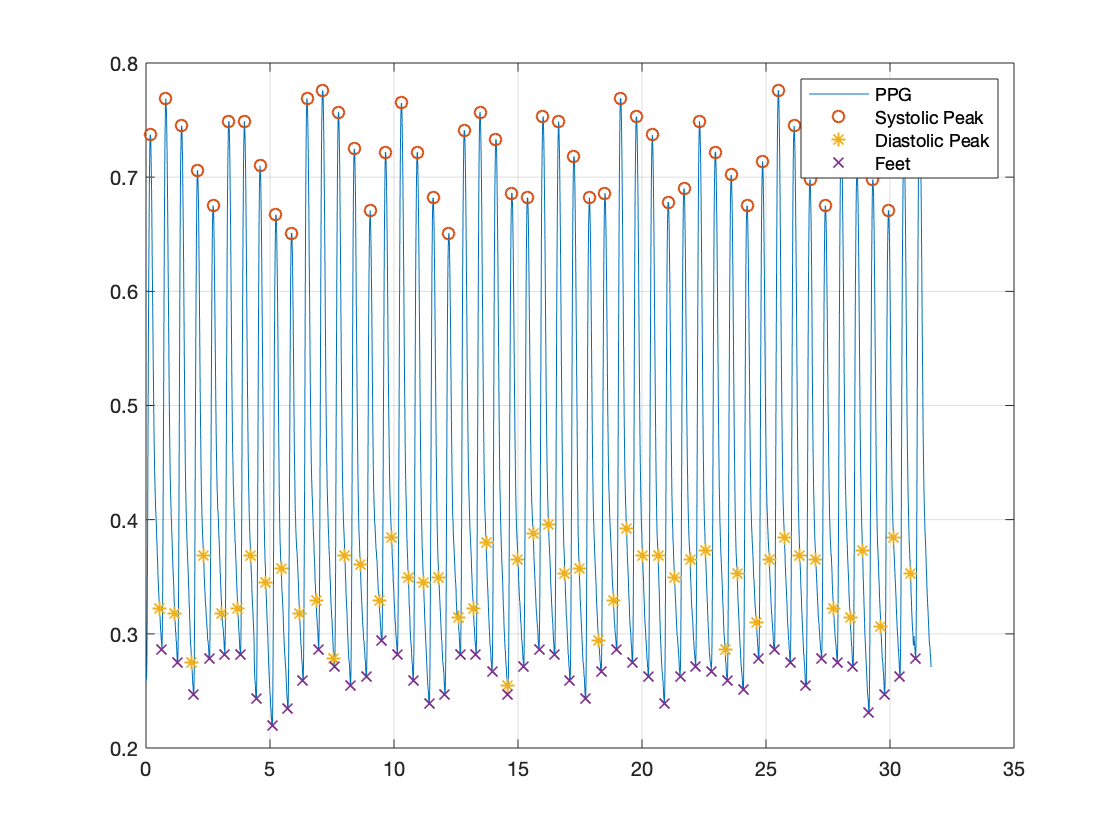

addpath('./TimeFeatures')
data = importdata("../physionet.org/segmented_data/3739816_0022-0012.txt");
[sys, dias, feet] = findPPGPeaks(data(:,3), opts.samp_freq);

%sort the peaks: foot - sys - dias - next foot
%   this avoids issues if any point could not be found for a waveform
sortedPeaks = sortPPGPeaks(systolic_pts, diastolic_pts, feet);

clf
plot(data(:,1), data(:,3))
hold on
scatter(data(sortedPeaks(:,2),1), data(sortedPeaks(:,2),3), 'o', 'LineWidth',1);
scatter(data(sortedPeaks(:,3),1), data(sortedPeaks(:,3),3), '*', 'LineWidth',1)
scatter(data(sortedPeaks(:,1),1), data(sortedPeaks(:,1),3), 'x', 'LineWidth',1)
legend("PPG", "Systolic Peak", "Diastolic Peak", "Feet")
grid on

#### Systolic and Diastolic Peak Amplitudes

addpath('./TimeFeatures')
data = importdata("../physionet.org/segmented_data/3000393_0016-0009.txt");
[systolic_pts, diastolic_pts, feet] = findPPGPeaks(data(:,3), opts.samp_freq);
disp('Systolic Points')

Systolic Points


mean_amp = mean(data(systolic_pts,3))

mean_amp = 2.6740

dev_amp = std(data(systolic_pts,3))

dev_amp = 0.4107

max_amp = max(data(systolic_pts,3))

max_amp = 3.3710

min_amp = min(data(systolic_pts,3))

min_amp = 1.5220


disp('Diastolic Pts')

Diastolic Pts


mean_amp = mean(data(diastolic_pts,3))

mean_amp = 1.6999

dev_amp = std(data(diastolic_pts,3))

dev_amp = 0.5306

max_amp = max(data(diastolic_pts,3))

max_amp = 2.7100

min_amp = min(data(diastolic_pts,3))

min_amp = 0.7050

#### Heart Rate extraction from PPG

First the ppg foot waveform locations are extracted

Then these are used to find the HR (mean, max, most recent)

addpath('./TimeFeatures')
data = importdata("../physionet.org/segmented_data/3000393_0005-0015.txt");

[sys,dias,feet] = findPPGPeaks(data(:,3), opts.samp_freq);
sortedFeatures = sortPPGPeaks(sys, dias, feet);
[hr_avg, hr_max, hr_most_rec] = heartRateFromPPG(sortedFeatures(:,1), sortedFeatures(:,4), opts.samp_freq)

hr_avg = 75.7632

hr_max = 80.6452

hr_most_rec = 74.2574

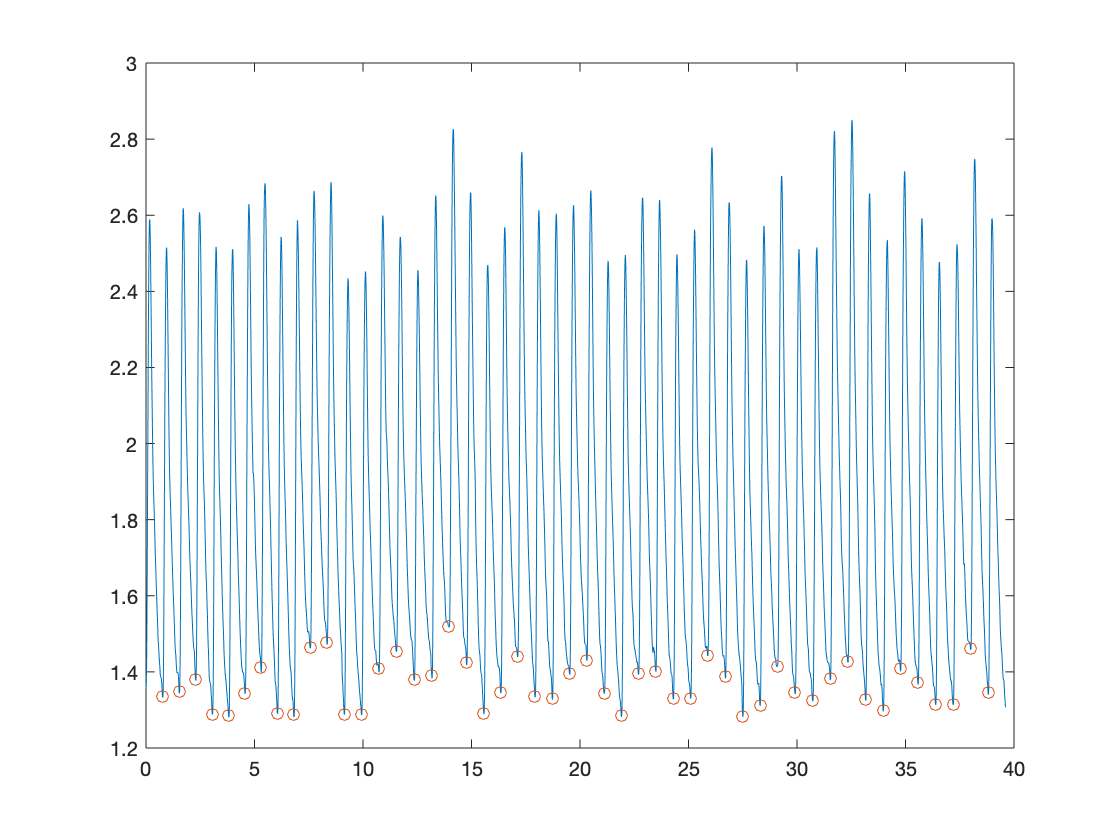


clf
plot(data(:,1), data(:,3))
hold on
scatter(data(ppg_feet,1), data(ppg_feet,3))

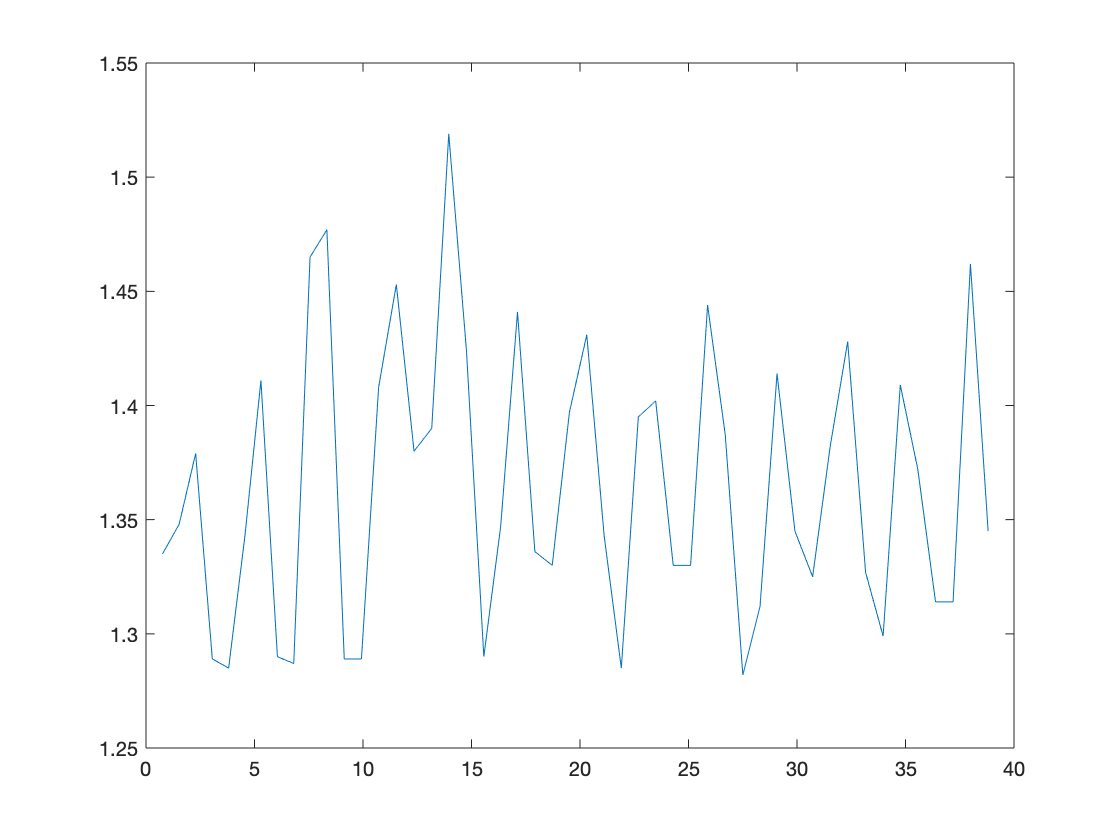

clf
plot(data(ppg_feet,1), data(ppg_feet,3))

#### PPG Time, Height, Area Intervals

Pulse Area (PA) - total area between feet

Inflection point area (IPA) - ratio of area in systole to ratio of area in diastole

Augmentation Index (AI) : height of diastolic peak:height of systolic peak

Peak-to-Peak time (ΔT) = time from systolic to diastolic peak (when no clear peak exists use the local max on the first derivative)

Large artery stiffness index(SI) = subject's height/ΔT (not currently possible)

Crest time (CT)= time between foot of wave to peak

        source: M. Elgendi, "On the analysis of fingertip photoplethysmogram signals"

addpath('./TimeFeatures')
data = importdata("../physionet.org/segmented_data/3000393_0016-0009.txt");
[systolic_pts, diastolic_pts, feet] = findPPGPeaks(data(:,3), opts.samp_freq);

sortedPeaks = sortPPGPeaks(systolic_pts, diastolic_pts, feet);

[PA, IPA, AI] = ppgAreaAndHeightFeatures(data(:,3), sortedPeaks);
deltaT = (sortedPeaks(:,3)-sortedPeaks(:,2))./opts.samp_freq;
CT = (sortedPeaks(:,2)-sortedPeaks(:,1))./opts.samp_freq;

fprintf('PA - mean: %.4f \t std dev: %.4f', mean(PA), std(PA))

PA - mean: 84.2254 	 std dev: 37.9611

fprintf('IPA - mean: %.4f \t std dev: %.4f', mean(IPA), std(IPA))

IPA - mean: 0.1839 	 std dev: 0.2176

fprintf('AI - mean: %.4f \t std dev: %.4f', mean(AI), std(AI))

AI - mean: 0.6300 	 std dev: 0.1675

fprintf('ΔT - mean: %.4f s \t std dev: %.4f s', mean(deltaT), std(deltaT))

ΔT - mean: 0.3588 s 	 std dev: 0.1633 s

fprintf('CT - mean: %.4f s \t std dev: %.4f s', mean(CT), std(CT))

CT - mean: 0.3053 s 	 std dev: 0.0812 s

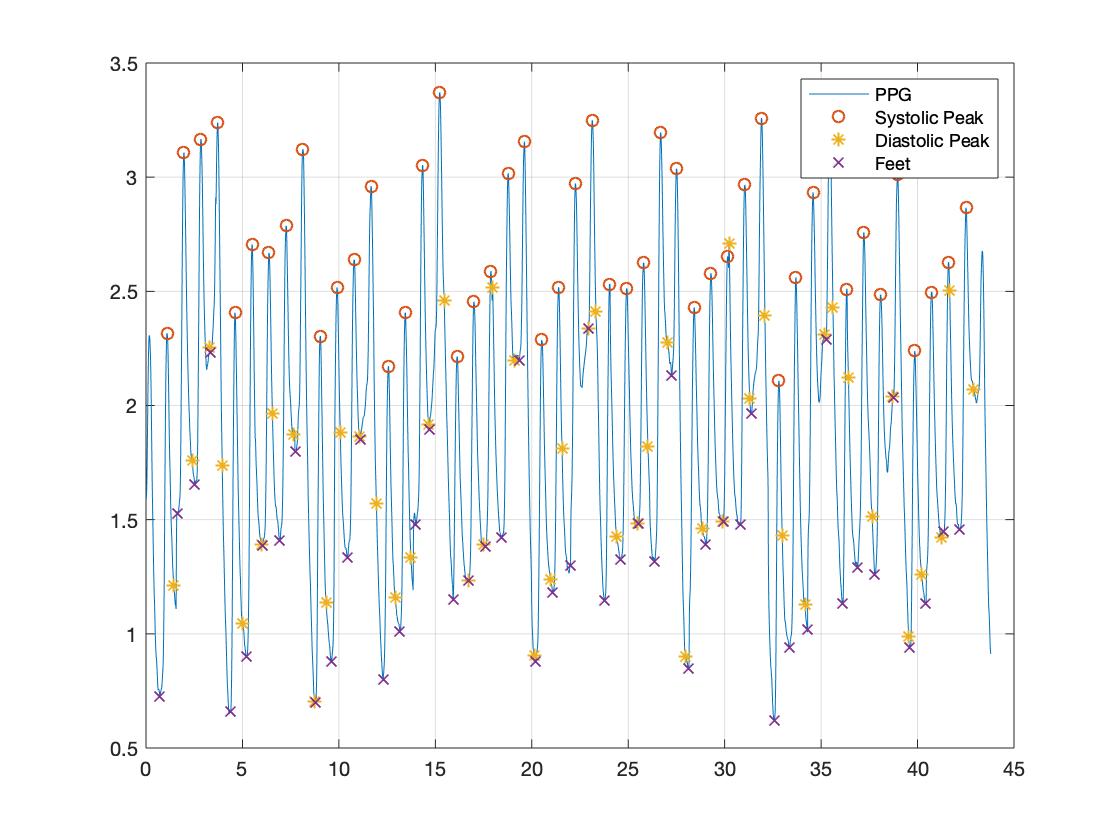


clf
plot(data(:,1), data(:,3))
hold on
scatter(data(sortedPeaks(:,2),1), data(sortedPeaks(:,2),3), 'o', 'LineWidth',1);
scatter(data(sortedPeaks(:,3),1), data(sortedPeaks(:,3),3), '*', 'LineWidth',1)
scatter(data(sortedPeaks(:,1),1), data(sortedPeaks(:,1),3), 'x', 'LineWidth',1)
legend("PPG", "Systolic Peak", "Diastolic Peak", "Feet")
grid on

#### Respiratory rate from PPG

See P.S.Addison et al. [https://sci-hub.se/10.1007/s10877-011-9332-y](https://sci-hub.se/10.1007/s10877-011-9332-y)

Typical freq range of respiration is [2.97;28.02] breaths/min <=> [0.05;0.47] Hz. A heart rate of [45;220] bpm <=> [0.75; 3.67] Hz ie. signals should be able to be separated

addpath('./TimeFeatures')
data = importdata("../physionet.org/segmented_data/3161587_0039-0024.txt");


resp_rate_hz = getRespiratoryRateFreq(data(:,1), data(:,3))

resp_rate_hz = 0.2446

resp_rate_bpm = resp_rate_hz*60

resp_rate_bpm = 14.6758

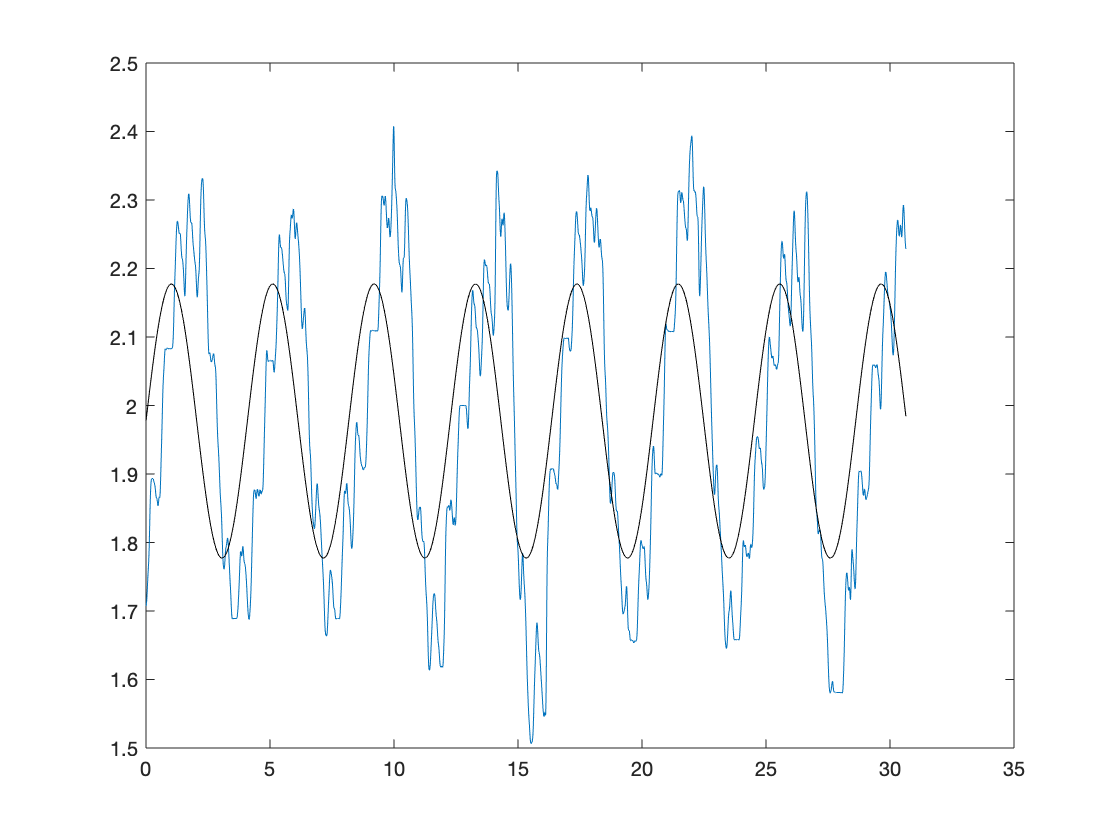


clf
plot(data(:,1), data(:,3))
hold on
plot(data(:,1), 0.2.*sin(2*pi*resp_rate_hz.*data(:,1))+mean(data(:,3)), 'Color', 'black')

#### Feature Scaling Factors

Roughly, the range of features should not be greater than [-1,1] and not smaller than [-1/3; 1/3] 

Normalisation should not be applied alone on each signal because every signal should have the same shift and scaling applied ie. need to calculate every feature's mean and std deviation across all files. This includes for the input ppg waveform and output ABP waveform.

Averaging standard deviations is done by averaging the variances and then square rooting.

%Structure of each scaling variable = [mean, variance] where each row represents
%   a different file
fileList = dir(opts.segmented_file_dir+"*.txt");
numFiles = length(fileList)

numFiles = 8635

ppg = zeros(numFiles,2);
abp = zeros(numFiles,2);
systolic_peak_amplitudes = zeros(numFiles,2);
diastolic_peak_amplitudes = zeros(numFiles,2);
feet_amplitudes = zeros(numFiles,2);
%the features below will be single valued ie just store the mean and the
%variance is calculated at the end
PA = zeros(numFiles,1);
IPA = zeros(numFiles,1);
AI = zeros(numFiles,1);
deltaT = zeros(numFiles,1);
CT = zeros(numFiles,1);
heart_rate = zeros(numFiles,1);
resp_rate = zeros(numFiles,1);

fileList = dir(opts.segmented_file_dir+"*.txt");

numWorkers = 8;

parfor (idx = 1:numFiles, numWorkers)
    fprintf('\b\b\b\b\b %i', idx)
    
     dataFile = fopen(opts.segmented_file_dir + fileList(idx).name);
     data = cell2mat(textscan( dataFile, ...
         '%f %f %f', 'TreatAsEmpty', '-', 'EmptyValue', 0));
     fclose(dataFile);
     
     abp_wave = data(:,2);
     ppg_wave = data(:,3);
     
     abp(idx,:) = [mean(abp_wave), std(abp_wave)^2];
     ppg(idx,:) = [mean(ppg_wave), std(ppg_wave)^2];
     
    [sys,dias,feet] = findPPGPeaks(ppg_wave, opts.samp_freq);
    sortedFeatures = sortPPGPeaks(sys, dias, feet);
     
    systolic_peak_amplitudes(idx,:) = [mean(ppg_wave(sortedFeatures(:,2))), std(ppg_wave(sortedFeatures(:,2)))^2];
    diastolic_peak_amplitudes(idx,:) = [mean(ppg_wave(sortedFeatures(:,3))), std(ppg_wave(sortedFeatures(:,3)))^2];
    feet_amplitudes(idx,:) = [mean(ppg_wave(sortedFeatures(:,1))), std(ppg_wave(sortedFeatures(:,1)))^2];
   
    heart_rate = [heart_rate; heartRateFromPPG(sortedFeatures(:,1), sortedFeatures(:,4), opts.samp_freq)];
    
    resp_rate = [resp_rate; getRespiratoryRateFreq(data(:,1), ppg_wave)];
    
    [currPA, currIPA, currAI] = ppgAreaAndHeightFeatures(data(:,3), sortedFeatures);
    PA(idx,:) = [mean(currPA)];
    IPA(idx,:) = [mean(currIPA)];
    AI(idx,:) = [mean(currAI)];
    deltaT(idx,:) = [mean((sortedFeatures(:,3)-sortedFeatures(:,2))./opts.samp_freq)];
    CT(idx,:) = [mean((sortedFeatures(:,2)-sortedFeatures(:,1))./opts.samp_freq)];

end

 8635


ppg_factor = [mean(ppg(:,1)), sqrt(mean(ppg(:,2)))]

ppg_factor =     0.9706    0.3254


abp_factor = [mean(abp(:,1)), sqrt(mean(abp(:,2)))]

abp_factor =    79.6121   22.2472


systolic_peak_amplitudes_factor = [mean(systolic_peak_amplitudes(:,1)), sqrt(mean(systolic_peak_amplitudes(:,2)))]

systolic_peak_amplitudes_factor =     1.3836    0.1669


diastolic_peak_amplitudes_factor = [mean(diastolic_peak_amplitudes(:,1)), sqrt(mean(diastolic_peak_amplitudes(:,2)))]

diastolic_peak_amplitudes_factor =     0.9013    0.2232


feet_amplitudes_factor = [mean(feet_amplitudes(:,1)), sqrt(mean(feet_amplitudes(:,2)))]

feet_amplitudes_factor =     0.6989    0.1564


%the features below will be single valued ie just store the mean and the
%variance is calculated at the end
PA_factor = [mean(PA), std(PA)]

PA_factor =    30.2371   30.3701


IPA_factor = [mean(IPA), std(IPA)]

IPA_factor =     0.2650    0.3202


AI_factor = [mean(AI), std(AI)]

AI_factor =     0.6307    0.1586


deltaT_factor = [mean(deltaT), std(deltaT)]

deltaT_factor =     0.2904    0.1019


CT_factor = [mean(CT), std(CT)]

CT_factor =     0.1781    0.0343


heart_rate_factor = [mean(heart_rate), std(heart_rate)]

heart_rate_factor =    45.5135   47.1093


resp_rate_factor = [mean(resp_rate), std(resp_rate)]

resp_rate_factor =     0.1247    0.1259


% Frequency and Phase

data = importdata("../physionet.org/segmented_data/3000063_0016-0024.txt");

Ts = mean(diff(data(:,1)));

[p, shift, ppg_shift, abp_shift, t_shift] = checkCorrelation(data(:,1), data(:,2), data(:,3));
shift = round(shift/Ts)

shift = 340

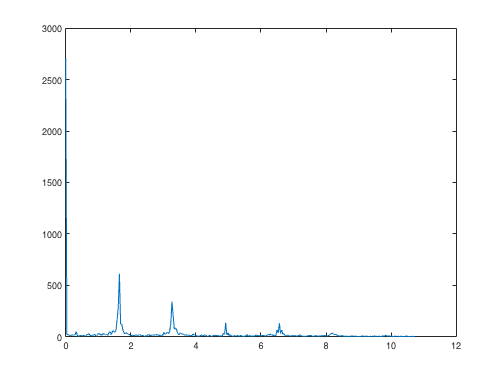




[f, fftABPshift] = singlesidedFFT(t_shift, abp_shift);
[~, fftPPGshift] = singlesidedFFT(t_shift, ppg_shift);

clf
plot(f(1:300),abs(fftABPshift(1:300)))

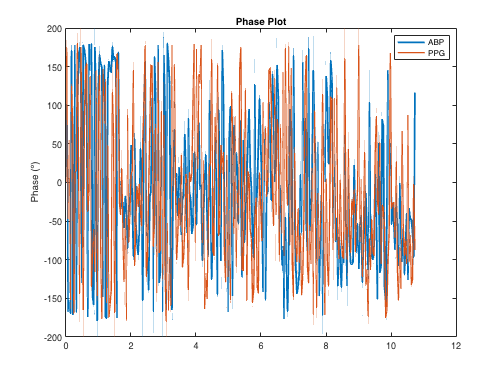

clf
plot(f(1:300),angle(fftABPshift(1:300)).*180/pi,'LineWidth',2)
hold on
plot(f(1:300),angle(fftPPGshift(1:300)).*180/pi, 'LineWidth',1.5)
legend("ABP", "PPG")
ylabel("Phase (º)")
title("Phase Plot")

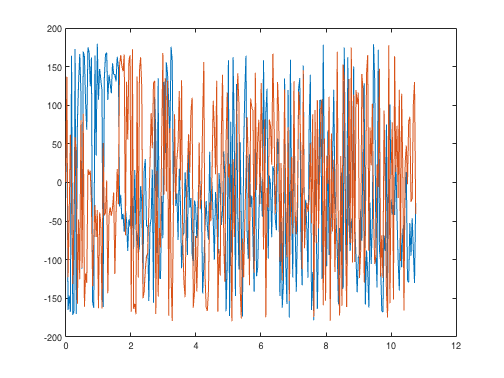


%original phase plots
[forig, fftABPorig] = singlesidedFFT(t, data(:,2));
[~, fftPPGorig] = singlesidedFFT(t, data(:,3));
clf;
plot(forig(1:300),angle(fftABPorig(1:300)).*180/pi)
hold on
plot(forig(1:300),angle(fftPPGorig(1:300)).*180/pi)

% legend("ABP", "PPG")
% ylabel("Phase (º)")
% title("Original Phase Plot")


%Average diff btwn phases
mse_phase_orig = mean((angle(fftABPorig)-angle(fftPPGorig)).^2)

mse_phase_orig = 8.9426

mse_phase_shifted = mean((angle(fftABPshift)-angle(fftPPGshift)).^2)

mse_phase_shifted = 1.1436

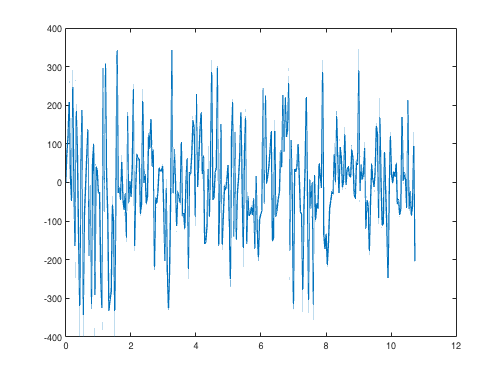


clf
plot(f(1:300),(angle(fftPPG(1:300))-angle(fftABP(1:300))).*180/pi, 'LineWidth',1.5)

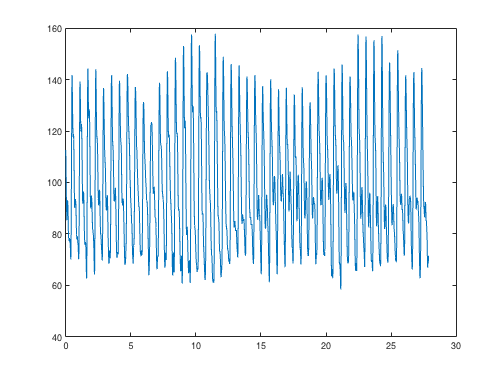


phaseDiff = (angle(fftPPG)-angle(fftABP));
[~, maxDiffIndices] = maxk(abs(phaseDiff), 200);
maxDiff = phaseDiff(maxDiffIndices);
reconABPPhase = angle(fftPPG);
reconABPPhase(maxDiffIndices) = - maxDiff + reconABPPhase(maxDiffIndices);

reconABP = abs(fftABP).*(cos(reconABPPhase)+sqrt(-1).*sin(reconABPPhase));

[reconTime, reconABPtime] = singlesidedIFFT(f, reconABP);
plot(reconTime, reconABPtime)

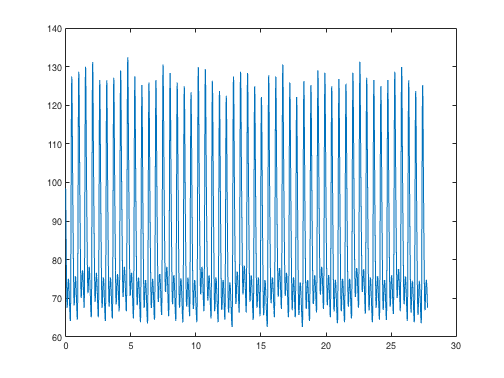

clf
plot(t,abp)

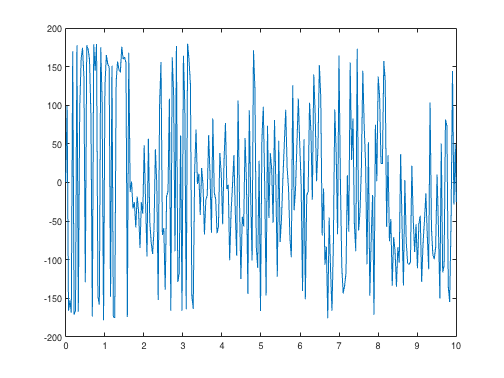

plot(f, angle(fftABPshift).*180/pi)
xlim([0,10])


[~, maxFreqIndices] = maxk(abs(fftABPshift), 100);
% [~,maxFreqIndices] = findpeaks(abs(fftABPshift), 'NPeaks', 30, "SortStr", "descend");

reconABPPhase = 0.*angle(fftPPGshift);
reconABPPhase(maxFreqIndices) = angle(fftABPshift(maxFreqIndices));

% envelopePhase = envelope(angle(fftABPshift), 16, 'peaks')';
% envelopePhase = envelopePhase'.*angle(fftPPGshift)%.*sin(2*pi*14.3.*f);
reconABPfft = abs(fftABPshift).*exp(1i.*reconABPPhase)

reconABPfft = 	1.0e+03 *

   2.7141 + 0.0000i
  -0.0030 + 0.0188i
  -0.0194 - 0.0046i
   0.0131 + 0.0000i
   0.0132 + 0.0000i
   0.0135 + 0.0000i
   0.0134 + 0.0000i
  -0.0185 - 0.0043i
  -0.0174 + 0.0006i
  -0.0475 - 0.0104i


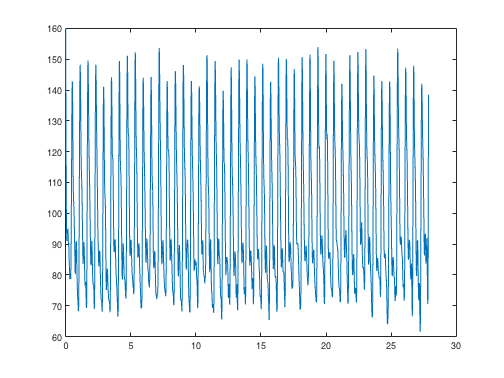


[reconT, reconABP] = singlesidedIFFT(f, reconABPfft);
clf
plot(reconT, reconABP)
ylim([60,160])

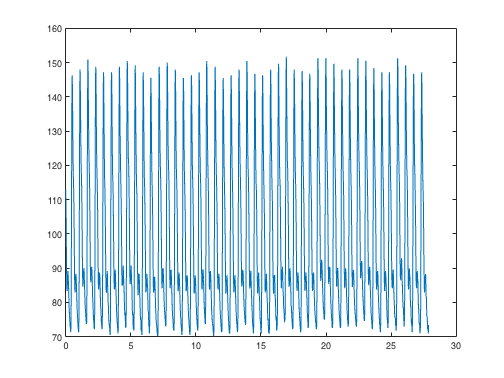

clf 
plot(t_shift, abp_shift)